clearvars;
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 1;
yint = 1;
zint = 1;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 20; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
location = [];
z = zmin;
%dataavg = [];

for k = 1:ztotal
    zstr = sprintf('%.1f', z);
    y = ymin;

    for j = 1:ytotal
        ystr = sprintf('%.1f', y);
        x = xmin;

        for i = 1:xtotal

            xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\Gitub\magnetic-sensor-data\PIM06072023_2cmAbove\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
            location = [location
                [x y z]];
           
            x = x + xint;
        end
        y = y + yint;
    end
    z = z + zint;
end

%writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_averages.txt');
%writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_locations.txt')

location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_locations.txt');
dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_averages.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.041559     0.098701    -0.050297
    -0.040386     0.099252    -0.050249
    -0.038522      0.10008    -0.050136
    -0.035891      0.10087    -0.050105
    -0.032876      0.10146    -0.050186
     -0.02932      0.10219    -0.050124
    -0.024906      0.10293    -0.049934
    -0.021925       0.1032    -0.049798
    -0.018895      0.10302    -0.049953
    -0.015406      0.10244    -0.050211


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =     -0.022956     0.027452    -0.017373
    -0.023214     0.027921    -0.017437
    -0.023668     0.028455    -0.017549
    -0.024243     0.029275    -0.017783
    -0.024868      0.03021    -0.017916
    -0.025722     0.031239     -0.01816
    -0.026857     0.032835    -0.018313
    -0.027615     0.033974     -0.01842
     -0.02832     0.035171    -0.018602
    -0.029176     0.036543    -0.018764


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =      -0.19879     -0.19829     -0.19873
     -0.19879     -0.19829     -0.19873
     -0.19879     -0.19828     -0.19873
      -0.1988     -0.19827     -0.19873
     -0.17336     -0.19826     -0.19873
     -0.13183     -0.19825     -0.19874
    -0.076327     -0.19823     -0.19874
    -0.037746     -0.19822     -0.19874
    0.0023805     -0.19821     -0.19874
     0.049047      -0.1982     -0.19874


sen4 = dataavg(:,10:12) %top right sensor

sen4 =     -0.057798   0.00013472    -0.044679
     -0.05887  -0.00013735    -0.044639
    -0.060648  -0.00046083    -0.044577
    -0.063199  -0.00097907    -0.044527
    -0.065875   -0.0015368    -0.044358
    -0.069303   -0.0023538    -0.044001
    -0.073735   -0.0034714    -0.043328
    -0.076915   -0.0044639    -0.042699
    -0.080348   -0.0053516    -0.042046
    -0.084695   -0.0064871    -0.041094


X1 = [0 0 0] - location + [0 0 20];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], 726, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =       0.38034      0.38034      0.95084
      0.32003      0.40004       1.0121
      0.24982      0.41637       1.0631
      0.17144       0.4286       1.1015
     0.087238      0.43619       1.1254
            0      0.43876       1.1335
    -0.087238      0.43619       1.1254
     -0.17144       0.4286       1.1015
     -0.24982      0.41637       1.0631
     -0.32003      0.40004       1.0121


testB = 2*sen3

testB =      -0.39758     -0.39658     -0.39746
     -0.39757     -0.39658     -0.39746
     -0.39759     -0.39656     -0.39746
      -0.3976     -0.39655     -0.39746
     -0.34672     -0.39653     -0.39746
     -0.26367      -0.3965     -0.39748
     -0.15265     -0.39647     -0.39747
    -0.075492     -0.39645     -0.39748
    0.0047609     -0.39643     -0.39748
     0.098095      -0.3964     -0.39748


Bdiff = expectB-testB

Bdiff =       0.77791      0.77692       1.3483
      0.71761      0.79662       1.4096
      0.64741      0.81293       1.4606
      0.56904      0.82515        1.499
      0.43396      0.83272       1.5228
      0.26367      0.83526       1.5309
     0.065416      0.83266       1.5228
     -0.09595      0.82505        1.499
     -0.25458      0.81279       1.4606
     -0.41813      0.79644       1.4096


max(Bdiff)

ans =        1.5123       1.5066       3.6246


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen3;
loc = location + [0 0 20];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =       0.86066      0.47062     -0.19438


fval =        152.24


fval/datasize

ans =        0.2097


sqrt(sum(angle.^2))

ans =             1


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
ind = 10;
d_data = testB;
loc = location + [0 0 20];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =       0.81631      0.44637     -0.36659


fval =        192.94


fval/datasize

ans =       0.26576


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 20];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 726, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =      -0.48508     -0.27403      0.13167
      -0.5094     -0.29919     0.068783
     -0.52481     -0.32406     5.17e-05
     -0.53004     -0.34789     -0.07254
      -0.5243      -0.3699     -0.14664
      -0.5074     -0.38934     -0.21967
     -0.47981     -0.40551     -0.28906
     -0.44261     -0.41787     -0.35244
     -0.39741     -0.42603     -0.40781
     -0.34618     -0.42982     -0.45371


expectB

expectB =       0.38034      0.38034      0.95084
      0.32003      0.40004       1.0121
      0.24982      0.41637       1.0631
      0.17144       0.4286       1.1015
     0.087238      0.43619       1.1254
            0      0.43876       1.1335
    -0.087238      0.43619       1.1254
     -0.17144       0.4286       1.1015
     -0.24982      0.41637       1.0631
     -0.32003      0.40004       1.0121


fabdiff = expectB - faB

fabdiff =       0.86541      0.65436      0.81917
      0.82943      0.69923      0.94332
      0.77463      0.74043       1.0631
      0.70148       0.7765       1.1741
      0.61154       0.8061        1.272
       0.5074       0.8281       1.3531
      0.39257       0.8417       1.4144
      0.27117      0.84647        1.454
      0.14759      0.84239       1.4709
     0.026149      0.82986       1.4658


max(fabdiff)

ans =        2.4981       2.1815       4.7633


%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X1 = [0 0 0] - location + [0 0 20];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 726, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      -0.48508     -0.27403      0.13167
      -0.5094     -0.29919     0.068783
     -0.52481     -0.32406     5.17e-05
     -0.53004     -0.34789     -0.07254
      -0.5243      -0.3699     -0.14664
      -0.5074     -0.38934     -0.21967
     -0.47981     -0.40551     -0.28906
     -0.44261     -0.41787     -0.35244
     -0.39741     -0.42603     -0.40781
     -0.34618     -0.42982     -0.45371


fixapreds

fixapreds =       -2.5925       2.8379           30
      -2.5925       2.8379           30
      -2.5922       2.8376           30
      -2.5919       2.8373           30
      -3.5108       3.4341           30
      -5.3237       4.4488           30
       -8.248        5.583           30
      -10.455       6.0146           30
       -12.73       6.0724           30
      -15.164       5.6983           30


fixafvalues

fixafvalues =      0.012947
     0.012947
     0.012946
     0.012946
     0.010402
    0.0077852
    0.0066037
     0.007051
     0.008625
     0.012153


fixadiff = fixapreds - loc

fixadiff =        2.4075       7.8379           10
       1.4075       7.8379           10
      0.40783       7.8376           10
     -0.59194       7.8373           10
      -2.5108       8.4341           10
      -5.3237       9.4488           10
       -9.248       10.583           10
      -12.455       11.015           10
       -15.73       11.072           10
      -19.164       10.698           10


max(fixadiff)

ans =        17.661        11.22       12.261


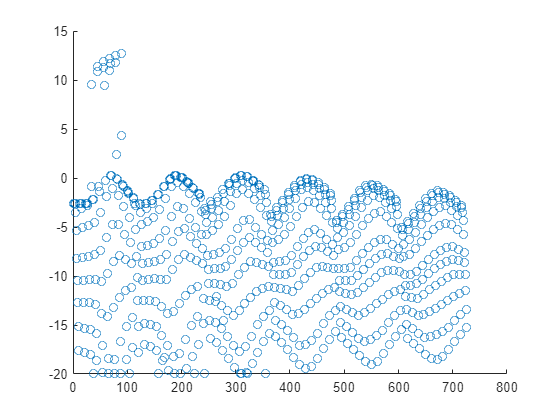

%predicted location using fixed angle
scatter(1:726,fixapreds(:,1)) %x values

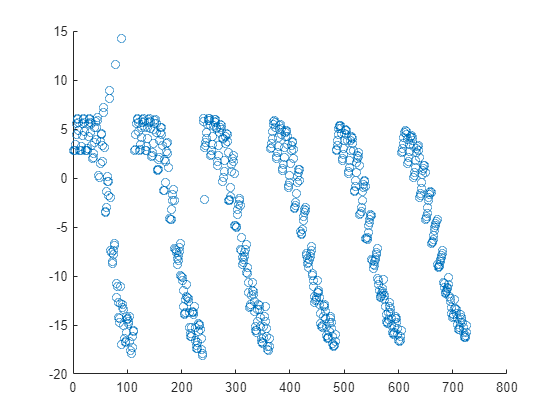

scatter(1:726,fixapreds(:,2)) %y values

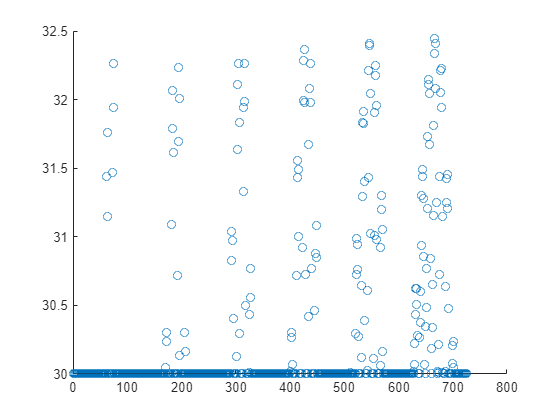

scatter(1:726,fixapreds(:,3)) %z values

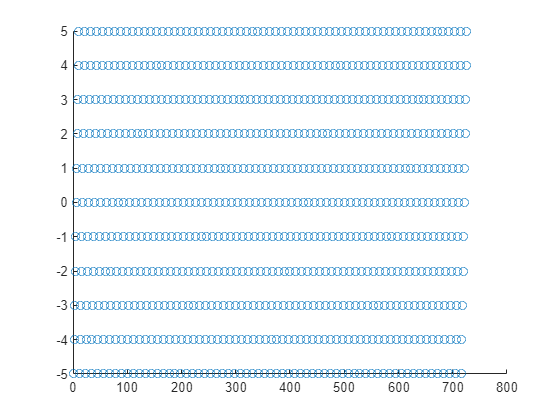

% scatter(1:121,fixadiff(:,1))
% scatter(1:121,fixadiff(:,2))
% scatter(1:121,fixadiff(:,3))

%actual location of measurement
scatter(1:726,loc(:,1))

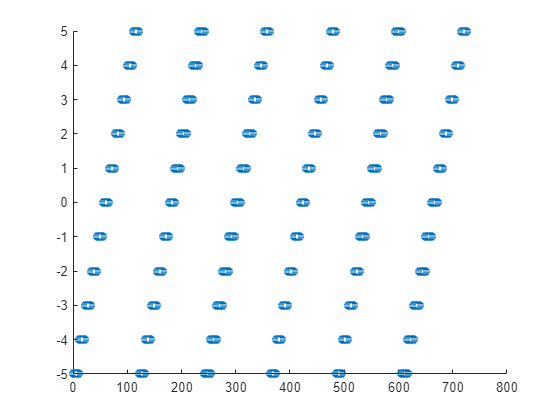

scatter(1:726,loc(:,2))

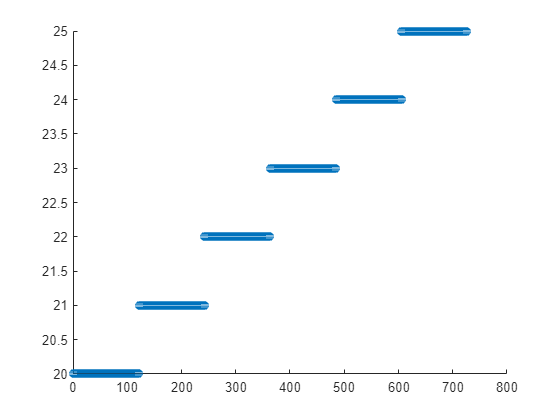

scatter(1:726,loc(:,3))

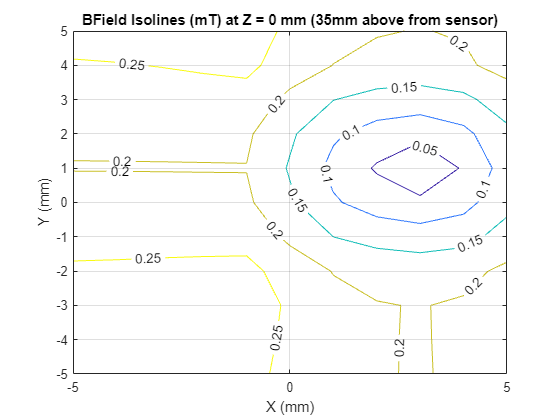

locavg = [location sen3];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (20mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

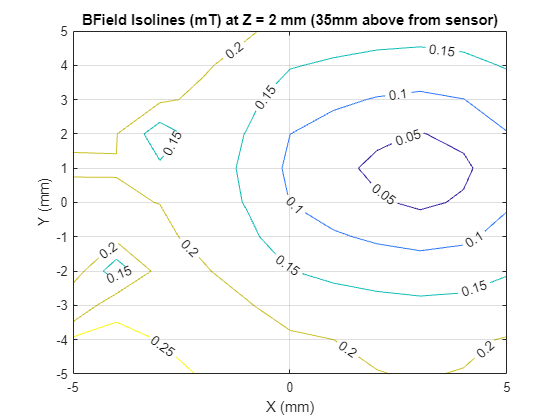

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 2 mm (20mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

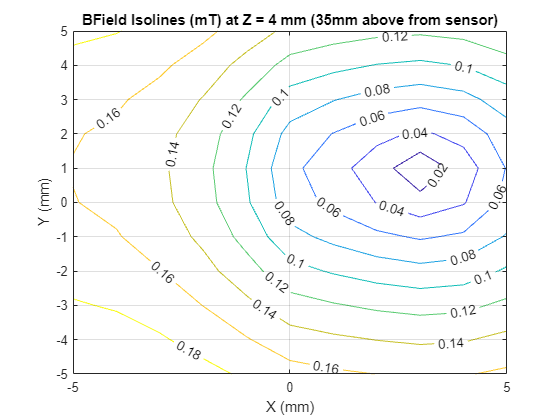

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (20mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:121,locpred(:,1)) %x values
% scatter(1:121,locpred(:,2)) %y values
% scatter(1:121,locpred(:,3)) %z values
% % scatter(1:121,fixadiff(:,1))
% % scatter(1:121,fixadiff(:,2))
% % scatter(1:121,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:121,loc(:,1))
% scatter(1:121,loc(:,2))
% scatter(1:121,loc(:,3))

% scatter(1:121, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:121, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:121, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end